AM调制的软件仿真实现

待处理信号

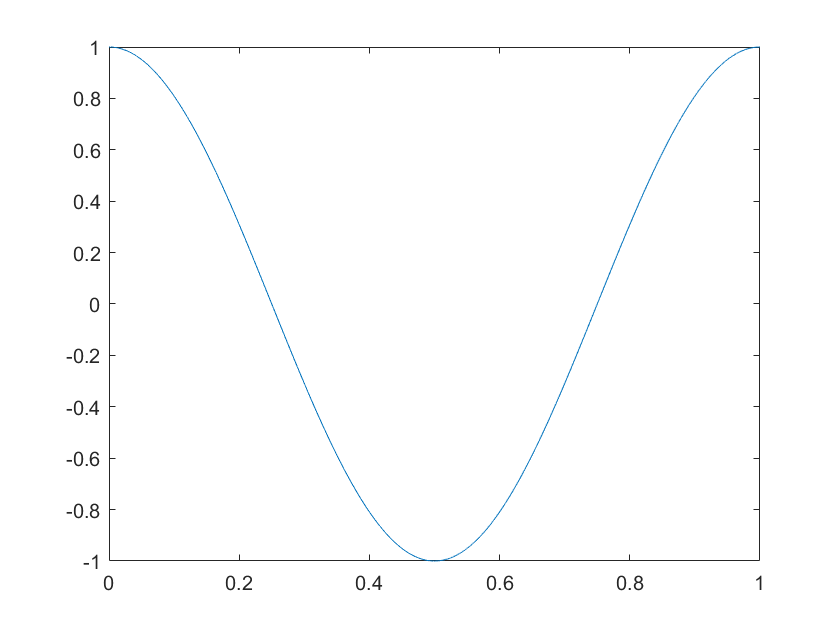

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

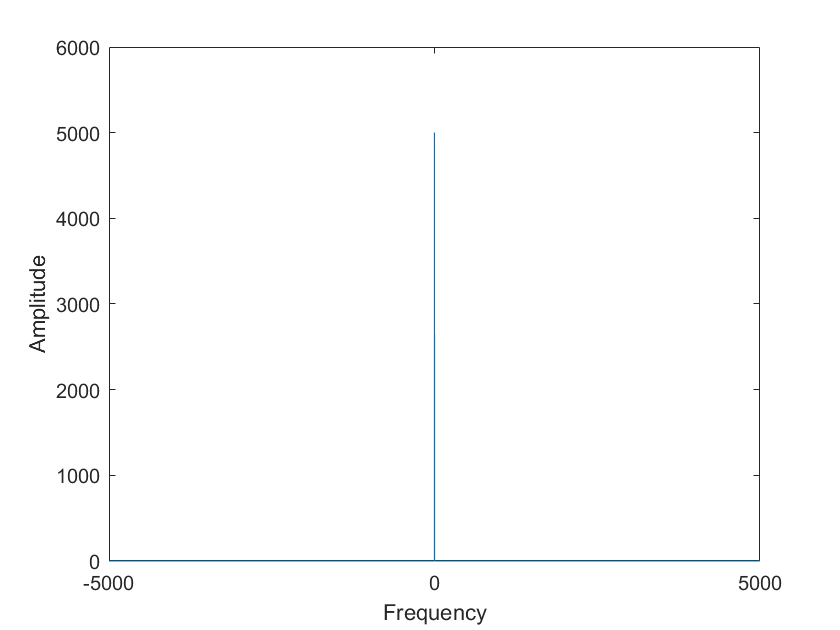

plotF(message, fs);

信号调制

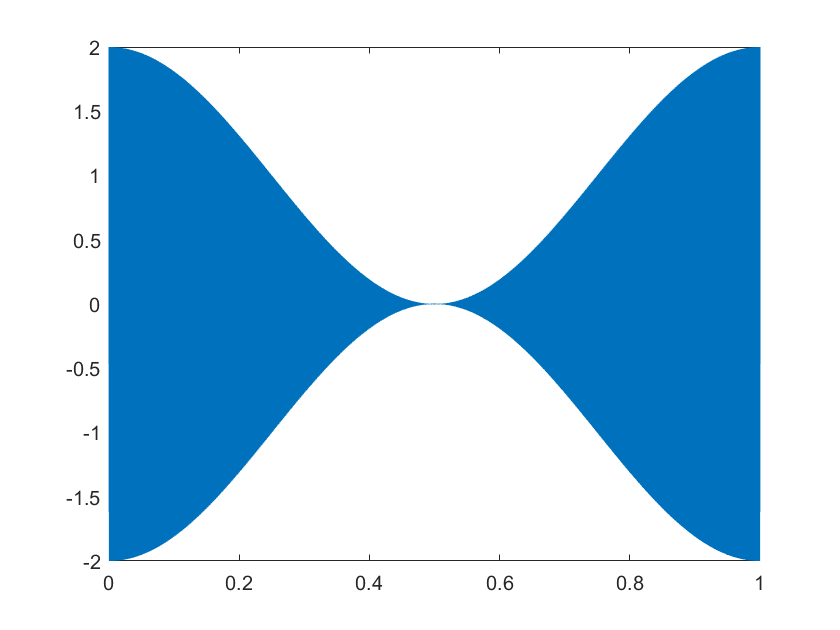

Ac = 1;
Km = 1;
carrier_frequency = 3000;
carrier = Ac*cos(2*pi*carrier_frequency*t);
modulated = (1 + Km * message).* carrier;
plot(t, modulated);

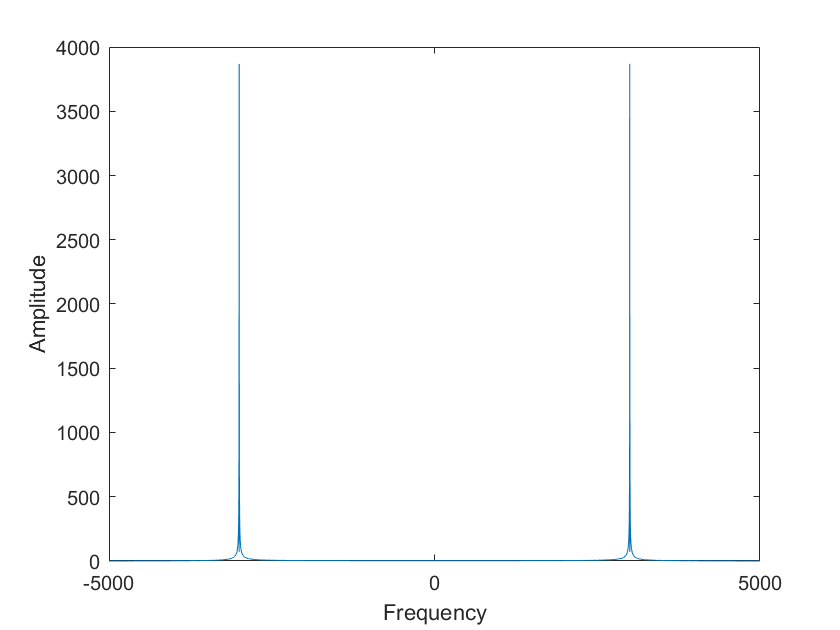

plotF(modulated, fs);

信道

sig_in_channel = modulated;

解调取包络

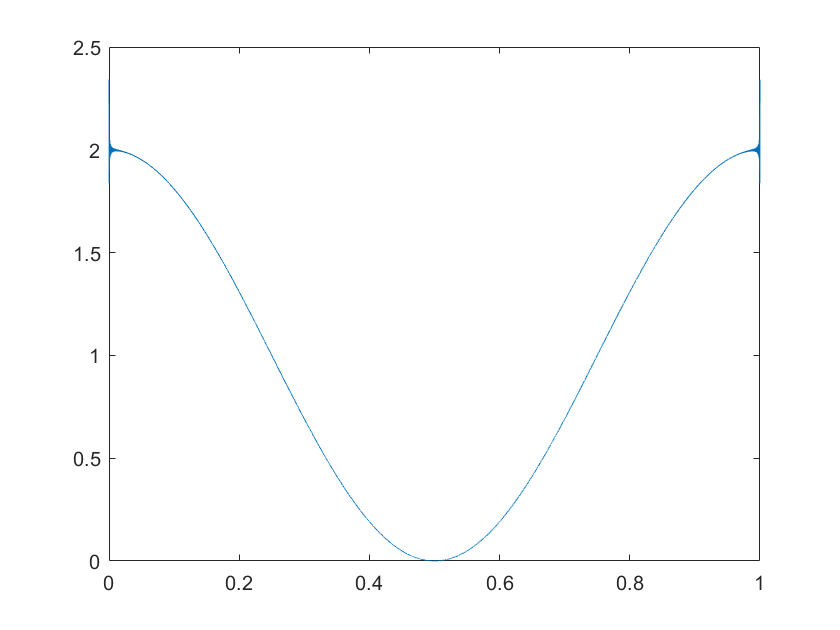

[demodulated_upper, demodulated_lower] = envelope(sig_in_channel);
plot(t, demodulated_upper)

去直流

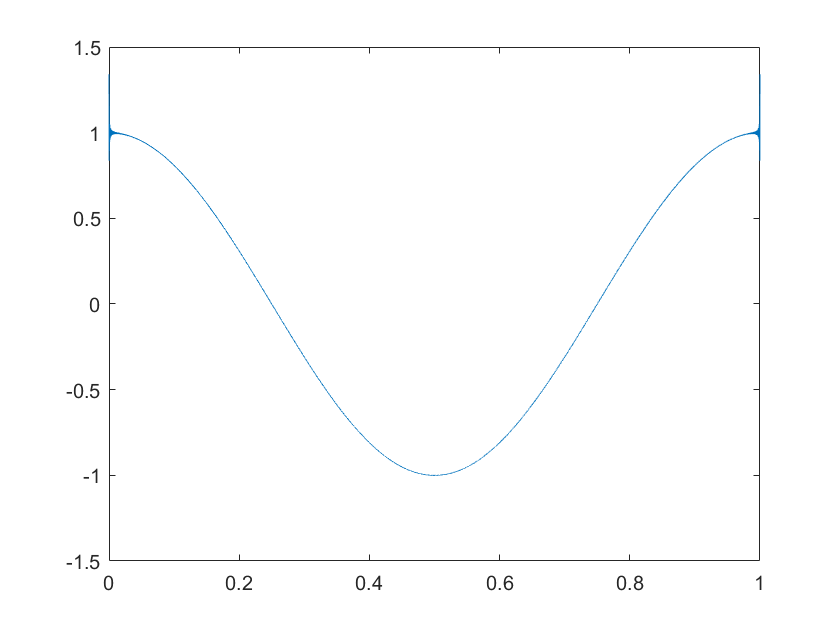

out = demodulated_upper - mean(demodulated_upper);
plot(t, out);